# Filtro de media movil exponencial (EMA)

Este filtro actua como un pasabajos eliminando ruido de alta frecuencia. Solo depende de un parametro. Este filtro tiene la siguiente ecuacion en diferencias


$$y(n)=\alpha x(n)+(1-\alpha)y(n-1)$$


Lo que entrega la funcion de transferencia


$$H(z)=\frac{Y(z)}{X(z)}=\frac{\alpha}{1-(1-\alpha) z^-1} =\frac{\alpha z}{z-(1-\alpha)}$$


A continuacion un ejemplo

n=0:511;% vector de tiempo
k=n/512;% vector de frecuencias
xn=sin(2*pi*n*1/4)+sin(2*pi*n*1/8)+sin(2*pi*n*1/32)+sin(2*pi*n*1/128);
xk=abs(fft(xn));

Se grafican la señal y su respectivo espectro de frecuencia

Identifique cada frecuencia y su ubicación en el dominio de la frecuencia

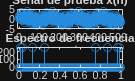

figure()
subplot(2,1,1);
stem(n,xn);
xlabel('muestras')
title('Señal de prueba x(n)');
subplot(2,1,2);
stem(k,xk);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

Se crea el filtro EMA

alfa = 0.1;
b = alfa;
a = [1 -(1-alfa)];

La aplicación del filtro sobre la señal se hace mediante la función filter

yn = filter(b,a,xn);
yk=abs(fft(yn));

Se procede a graficar la señal resultante y su espectro de frecuencia. Compare con las originales y advierta los cambios

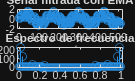

figure()
subplot(2,1,1)
stem(n,yn);
xlabel('muestras')
title('Señal filtrada con EMA');
subplot(2,1,2);
stem(k,yk);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');